syms s w_0 zeta omega_n p_0 p_1 p_2 b_4 k_D k_p k_i a b
eqn1 =(s-w_0)*(s^2+2*zeta*omega_n*s+omega_n^2)

$$eqn1 = \left(s-w_{0}\right)\,\left({\omega_{n}}^{2}+2\,\zeta \,\omega_{n}\,s+s^{2}\right)$$

eqn1 = expand(eqn1)

$$eqn1 = {\omega_{n}}^{2}\,s-w_{0}\,{\omega_{n}}^{2}+2\,\zeta \,\omega_{n}\,s^{2}-2\,w_{0}\,\zeta \,\omega_{n}\,s+s^{3}-w_{0}\,s^{2}$$

eqn2 = (s-p_0)*(s-p_1)*(s-p_2)+b_4*(k_D*s^2+k_p*s+k_i)

$$eqn2 = b_{4}\,\left(k_{D}\,s^{2}+k_{p}\,s+k_{i}\right)-\left(p_{0}-s\right)\,\left(p_{1}-s\right)\,\left(p_{2}-s\right)$$

eqn2 = expand(eqn2)

$$eqn2 = b_{4}\,k_{i}-p_{0}\,s^{2}-p_{1}\,s^{2}-p_{2}\,s^{2}+s^{3}+b_{4}\,k_{p}\,s-p_{0}\,p_{1}\,p_{2}+p_{0}\,p_{1}\,s+p_{0}\,p_{2}\,s+p_{1}\,p_{2}\,s+b_{4}\,k_{D}\,s^{2}$$


%Identify expressions
identity = coeffs(eqn1,s) == coeffs(eqn2,s);
identity = identity(1:3)

$$identity = \left(\begin{array}{ccc} -{\omega_{n}}^{2}\,w_{0}=b_{4}\,k_{i}-p_{0}\,p_{1}\,p_{2} & {\omega_{n}}^{2}-2\,\omega_{n}\,w_{0}\,\zeta =b_{4}\,k_{p}+p_{0}\,p_{1}+p_{0}\,p_{2}+p_{1}\,p_{2} & 2\,\omega_{n}\,\zeta -w_{0}=b_{4}\,k_{D}-p_{1}-p_{2}-p_{0} \end{array}\right)$$


%Solve for PID parameters
[k_p, k_i ,k_D] = solve(identity,[k_p k_i k_D]) 

$$k\_p = -\frac{-{\omega_{n}}^{2}+2\,w_{0}\,\zeta \,\omega_{n}+p_{0}\,p_{1}+p_{0}\,p_{2}+p_{1}\,p_{2}}{b_{4}}$$

$$k\_i = -\frac{{\omega_{n}}^{2}\,w_{0}-p_{0}\,p_{1}\,p_{2}}{b_{4}}$$

$$k\_D = \frac{p_{0}+p_{1}+p_{2}-w_{0}+2\,\omega_{n}\,\zeta }{b_{4}}$$

sol = [k_p;k_i;k_D]

$$sol = \left(\begin{array}{c} -\frac{-{\omega_{n}}^{2}+2\,w_{0}\,\zeta \,\omega_{n}+p_{0}\,p_{1}+p_{0}\,p_{2}+p_{1}\,p_{2}}{b_{4}}\\ -\frac{{\omega_{n}}^{2}\,w_{0}-p_{0}\,p_{1}\,p_{2}}{b_{4}}\\ \frac{p_{0}+p_{1}+p_{2}-w_{0}+2\,\omega_{n}\,\zeta }{b_{4}} \end{array}\right)$$

denominator = (k_D*s^2+k_p*s+k_i) %For finding zeros b_4 not interseting

$$denominator = \frac{s^{2}\,\left(p_{0}+p_{1}+p_{2}-w_{0}+2\,\omega_{n}\,\zeta \right)}{b_{4}}-\frac{s\,\left(-{\omega_{n}}^{2}+2\,w_{0}\,\zeta \,\omega_{n}+p_{0}\,p_{1}+p_{0}\,p_{2}+p_{1}\,p_{2}\right)}{b_{4}}-\frac{{\omega_{n}}^{2}\,w_{0}-p_{0}\,p_{1}\,p_{2}}{b_{4}}$$



%Entering numerical values
addpath("Viktor\LAB_A\")

load poles.mat
load LABA_CONT.mat
eqnden = solve(denominator == 0,s)

$$eqnden = \begin{array}{l} \left(\begin{array}{c} \frac{p_{0}\,p_{1}+p_{0}\,p_{2}+p_{1}\,p_{2}-{\omega_{n}}^{2}+\sigma_{1}+2\,\omega_{n}\,w_{0}\,\zeta }{\sigma_{2}}\\ \frac{p_{0}\,p_{1}+p_{0}\,p_{2}+p_{1}\,p_{2}-{\omega_{n}}^{2}-\sigma_{1}+2\,\omega_{n}\,w_{0}\,\zeta }{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{\omega_{n}}^{4}+4\,{\omega_{n}}^{3}\,w_{0}\,\zeta -2\,{\omega_{n}}^{2}\,p_{0}\,p_{1}-2\,{\omega_{n}}^{2}\,p_{0}\,p_{2}+4\,{\omega_{n}}^{2}\,p_{0}\,w_{0}-2\,{\omega_{n}}^{2}\,p_{1}\,p_{2}+4\,{\omega_{n}}^{2}\,p_{1}\,w_{0}+4\,{\omega_{n}}^{2}\,p_{2}\,w_{0}+4\,{\omega_{n}}^{2}\,{w_{0}}^{2}\,\zeta^{2}-4\,{\omega_{n}}^{2}\,{w_{0}}^{2}-8\,\omega_{n}\,p_{0}\,p_{1}\,p_{2}\,\zeta +4\,\omega_{n}\,p_{0}\,p_{1}\,w_{0}\,\zeta +4\,\omega_{n}\,p_{0}\,p_{2}\,w_{0}\,\zeta +4\,\omega_{n}\,p_{1}\,p_{2}\,w_{0}\,\zeta +{p_{0}}^{2}\,{p_{1}}^{2}-2\,{p_{0}}^{2}\,p_{1}\,p_{2}+{p_{0}}^{2}\,{p_{2}}^{2}-2\,p_{0}\,{p_{1}}^{2}\,p_{2}-2\,p_{0}\,p_{1}\,{p_{2}}^{2}+4\,p_{0}\,p_{1}\,p_{2}\,w_{0}+{p_{1}}^{2}\,{p_{2}}^{2}}\\ \sigma_{2}=2\,\left(p_{0}+p_{1}+p_{2}-w_{0}+2\,\omega_{n}\,\zeta \right) \end{array}$$

double(subs( eqnden,[w_0 zeta omega_n p_0 p_1 p_2 b_4],[w_0val zetaVal omegaVal poles(2) poles(3) poles(4) B(4)]))

ans =   -21.9435
 -475.0690


solNum = vpa(subs(sol,[p_0 p_1 p_2 b_4],[poles(2) poles(3) poles(4) B(4)]));

%Lastly determine pole placement using dominant second order pole method
w_0val = poles(2) % is set to p0(the pole at -400)

w_0val = -475.0690

zetaVal = 1/sqrt(2)  %damping ratio (I think lol) 1 is critically damped(I think) 

zetaVal = 0.7071

omegaVal = 5.7

omegaVal = 5.7000

sigma = zetaVal*omegaVal

sigma = 4.0305

ts = 4.6/sigma

ts = 1.1413

tr = 1.8/omegaVal %Rise time

tr = 0.3158


solNum = double(subs(solNum,[w_0 zeta omega_n],[w_0val,zetaVal,omegaVal])) % Putting in values

solNum =   -43.5872
 -342.1874
   -0.0902



%Generate transfer function
load SystemTransferFunction.mat
S = tf("s");
DEN = B(4)*(solNum(3)*S^2+solNum(1)*S+solNum(2))

DEN =
 
  8.123 s^2 + 3924 s + 3.081e04
 
Continuous-time transfer function.
Model Properties


CLTF = DEN/( (S-poles(2)) * (S-poles(3)) * (S-poles(4)) + DEN)

CLTF =
 
     8.123 s^2 + 3924 s + 3.081e04
  -----------------------------------
  s^3 + 483.1 s^2 + 3862 s + 1.543e04
 
Continuous-time transfer function.
Model Properties


poles = pole(CLTF);
poles(2:3)

ans =   -4.0305 + 4.0305i
  -4.0305 - 4.0305i


zero(CLTF)

ans =  -475.0690
   -7.9826


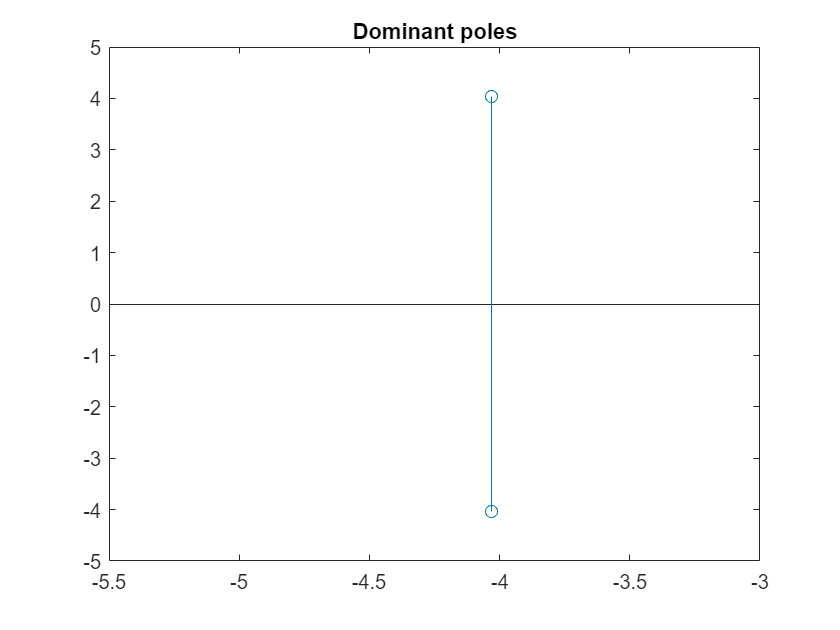

stem(real(poles(2:3)),imag(poles(2:3)))
title("Dominant poles")

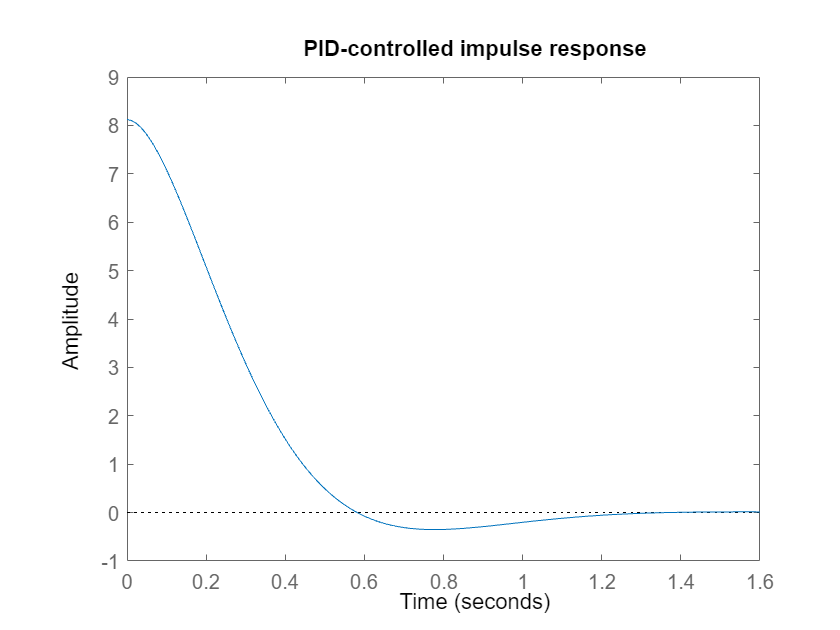


impulse(CLTF)
title("PID-controlled impulse response")

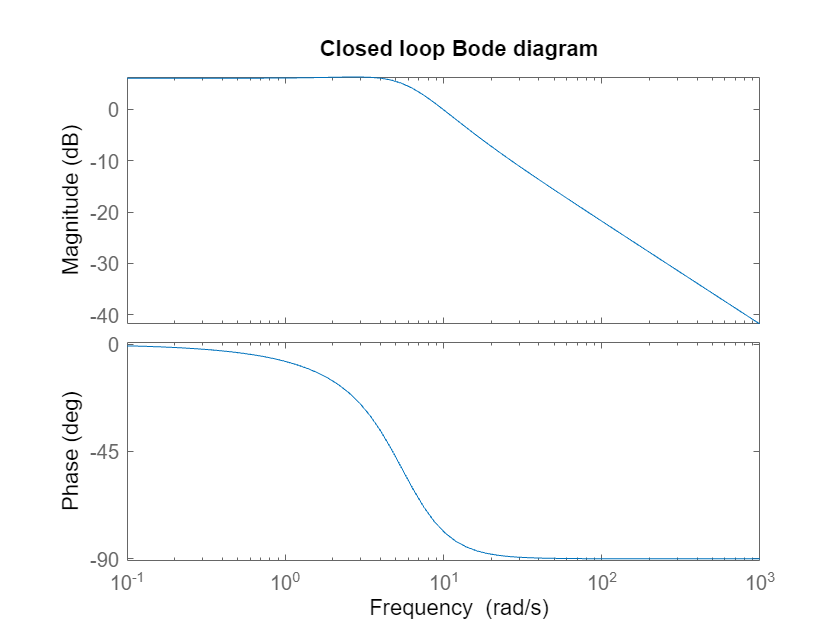

bode(CLTF)
title("Closed loop Bode diagram")

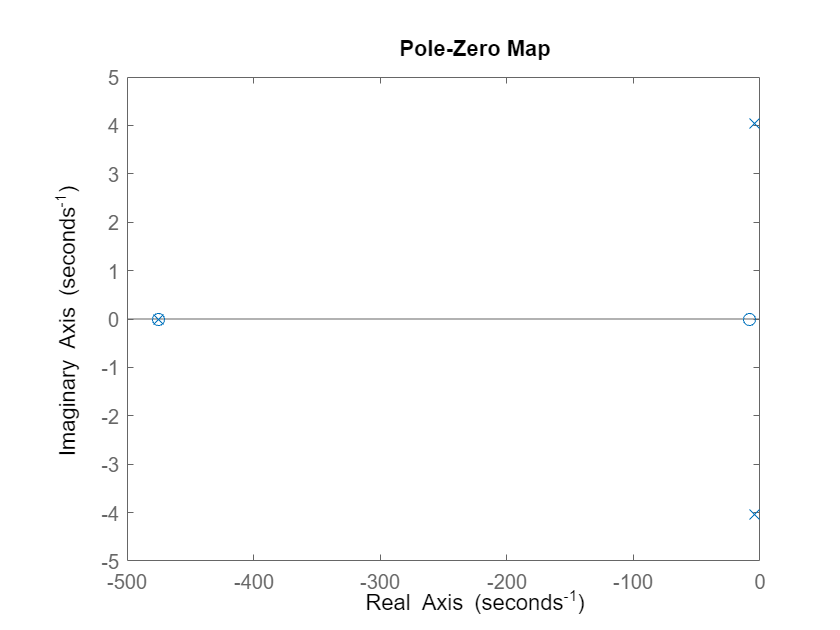

pzmap(CLTF)

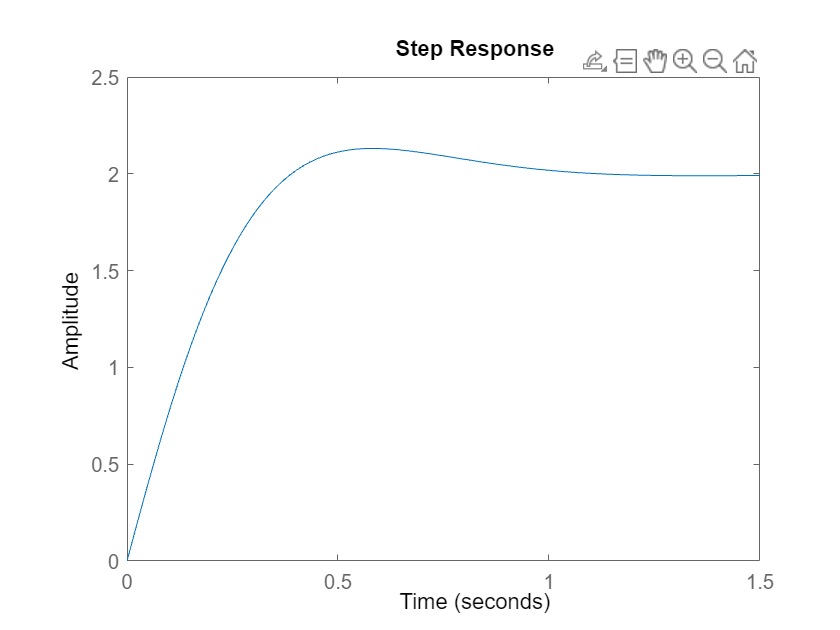

% %Note infinite gain margin but limited(though massive) phase margin

step(CLTF)


%Converting to discrete time
wb = bandwidth(CLTF) %Bandwith rad/s

wb = 7.2739

fb = wb/(2*pi) %Bandwidth Hz

fb = 1.1577

Fs =  200*fb %Sampling frequency

Fs = 231.5358

Ts = 1/Fs  %Sampling Period

Ts = 0.0043

simSamplePeriod = 0.00001

simSamplePeriod = 1.0000e-05

Tsd = floor(Ts/simSamplePeriod)*simSamplePeriod;
round(Ts,1,"significant")

ans = 0.0040



Kp = solNum(1)

Kp = -43.5872

Ki = solNum(2)

Ki = -342.1874

Kd = solNum(3)

Kd = -0.0902


save("LABA_CONT.mat","Kp","Ki","Kd","Ts","Tsd","simSamplePeriod","-append")


